##  Задание 3. Автономный генератор 

Параметры для запуска симуляции

simTimeStart = 0;
simTimeEnd = 20;
step = 0.02;
g = 1;
modelName = 'task3'; 

Высчитываем аналитическую модель...

syms t; syms a1; syms a2; syms a3; syms a4;
A = [0 2 0 0 ;
     -2 0 0 0;
     0 0 6 5;
     0 0 -5 6;]

A =      0     2     0     0
    -2     0     0     0
     0     0     6     5
     0     0    -5     6



exp(A*t)

$$ans = \left(\begin{array}{cccc} 1 & {\mathrm{e}}^{2\,t} & 1 & 1\\ {\mathrm{e}}^{-2\,t} & 1 & 1 & 1\\ 1 & 1 & {\mathrm{e}}^{6\,t} & {\mathrm{e}}^{5\,t}\\ 1 & 1 & {\mathrm{e}}^{-5\,t} & {\mathrm{e}}^{6\,t} \end{array}\right)$$

x0 = transpose([1 2 3 4]);
exp(A*t)*x0

$$ans = \left(\begin{array}{c} 2\,{\mathrm{e}}^{2\,t}+8\\ {\mathrm{e}}^{-2\,t}+9\\ 4\,{\mathrm{e}}^{5\,t}+3\,{\mathrm{e}}^{6\,t}+3\\ 3\,{\mathrm{e}}^{-5\,t}+4\,{\mathrm{e}}^{6\,t}+3 \end{array}\right)$$

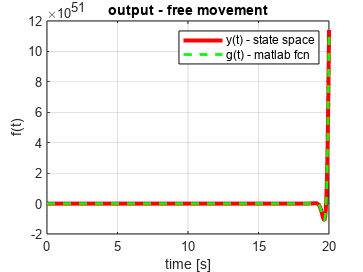

B = transpose([0 0 0 0]);
D = 0;
C = [1/5 2/5 3/25 4/25];

load_system(modelName);
out = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));

time = out.simout1.Time;                
y_out1 = out.simout1.Data; y_out2 = out.simout1.Data; 

figure;
plot(time, y_out1, 'r', 'LineWidth',3);
hold on;
plot(time, y_out2, 'g--', 'LineWidth',2);
title('output - free movement');   
xlabel('time [s]');                  
ylabel('f(t)');                      
grid on;
legend('y(t) - state space', 'g(t) - matlab fcn');
save_file('output_task3')

**Функция, чтобы сохранить файл в папку**

function save_file(name)
    path = 'D:\Math\LinearSystemsOfAutoControl\linear_systems_labs\lab2\latex2\images';
    fullpath = fullfile(path, name);
    saveas(gcf, fullpath, 'png');

end